waypoints = out.trajectory(:,1:3)

waypoints =          0         0         0
    0.0000    0.0000   -0.0026
    0.0000    0.0000   -0.0077
    0.0000    0.0000   -0.0151
    0.0000    0.0000   -0.0248
    0.0000    0.0000   -0.0366
    0.0000    0.0000   -0.0504
    0.0001    0.0001   -0.0662
    0.0001    0.0001   -0.0838
    0.0001    0.0001   -0.1031


numwpts = size(waypoints);


vels = 2*ones(numwpts);
accs = ones(numwpts);
jerks = zeros(numwpts);
snaps = zeros(numwpts);
yaws = zeros(1,numwpts(1));
starttime = 0;
endtime = 8;
toas = linspace(starttime,endtime,numwpts(1));

mrft = multirotorFlightTrajectory(waypoints,vels,accs,jerks,snaps,yaws,toas);
query(mrft,1:4)

ans =     0.1997    0.1997   -2.1347    2.0000    2.0000    2.0000    1.0000    1.0000    1.0000    0.9968    0.0564   -0.0560   -0.0032         0         0         0
    0.6531    0.6531   -1.8456    2.0000    2.0000    2.0000    1.0000    1.0000    1.0000    0.9968    0.0564   -0.0560   -0.0032         0         0         0
    0.9014    0.9014   -0.3105    2.0000    2.0000    2.0000    1.0000    1.0000    1.0000    0.9968    0.0564   -0.0560   -0.0032         0         0         0
    0.9871    0.9871    0.6700    2.0000    2.0000    2.0000    1.0000    1.0000    1.0000    0.9968    0.0564   -0.0560   -0.0032         0         0         0


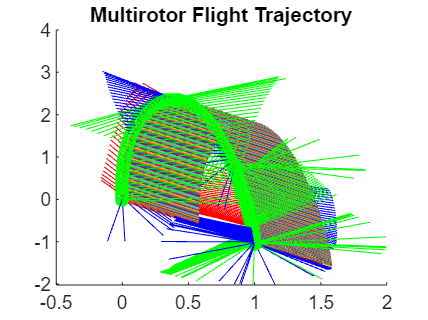


ax = show(mrft,NumSamples=200);
title("Multirotor Flight Trajectory")
view([0 0])